# Braccio Robotico Industriale

Si consideri un braccio robotico descritto da un modello non lineare, il cui **input** è la coppia applicata $u\left(t\right)=\tau \left(t\right)$ generata dal motore elettrico e la cui **uscita** è la velocità angolare del motore$y\left(t\right)=\frac{d}{\mathrm{dt}}q_{m\left(t\right)}$.

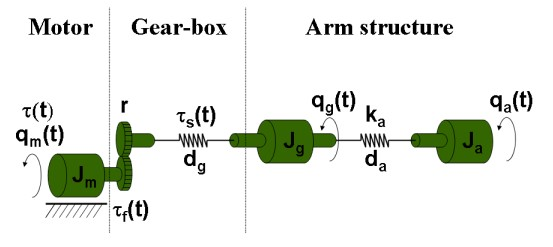

% In questo caso è misurabile soltanto la velocità angolare del motore q_m(t), mentre q_g(t)
% e q_a(t) sono considerati rumore. 

% Caricamento dataset
load robotarmdata

% Il sistema è descitto dal seguente sistema in forma di equazioni di stato 
% d/dt x1(t) = x3(t) - x4(t)
% d/dt x2(t) = x4(t) - x5(t)
% d/dt x3(t) = 1/(J*a_m)*(-tau_s(t) - d_g*(x3(t)-x4(t)) - tau_f(t) + u(t))
% d/dt x4(t) = 1/(J*a_g)*(tau_s(t) + d_g*(x3(t)-x4(t)) - k_a*x2(t) - d_a*(x4(t)-x5(t)))
% d/dt x5(t) = 1/(J(1-a_m-a_g))*(k_a*x2(t) + d_a*(x4(t)-x5(t)))
% 
%      y(t) = x3(t)

% Le non linearità sono presenti nelle espressioni delle coppie tau_f(t) (coppia della frizione della trasmissione) 
% tau_s(t) (coppia della molla)
% tau_f(t) = Fv*x3(t) + (Fc+Fcs/cosh(alpha*x3(t)))*tanh(beta*x3(t))
% tau_s(t) = k_g1*x1(t) + k_g3*x1(t)^3

% E i cui parametri sono i seguenti:
% Fv    = Coefficiente di attrito viscoso.            
% Fc    = Coefficiente di attrito di Coulomb.            
% Fcs   = Coefficiente di attrito di Striebeck.          
% alpha = Coefficiente di smoothness di Striebeck .        
% beta  = Coefficiente friction smoothness.         
% J     = Momento totale di inerzia.                 
% am    = Fattore di scala del momento di inerzia del motore.    
% ag    = Fattore di scala del momento di inerzia della trasmissione. 
% kg1   = Parametro di rigidezza della trasmissione 1.          
% kg3   = Parametro di rigidezza della trasmissione 3.          
% dg    = Parametro di smorzamento della trasmissione.              
% ka    = Parametro di rigidezza della struttura del braccio.       
% da    = Parametro di smorzamento della struttura del braccio.

% Prepariamo i dati di training
eData = iddata(ye,ue,5e-4,InputName="Torque", ...
    OutputName="Angular Velocity",Tstart=0);
% ue: è ottenuto come somma di sinusoidi con spettro ad ampiezza costante
% nell'intervallo 1-40 Hz e valore di picco pari a 16rad/s. Tale segnale
% viene sovrapposto ad un segnale onda quadra filtrato di ampiezza 20 rad/s
% e frequenza di cut-off 1Hz. 
% Effettuiamo un downsampling pari a 10 dei dati per rendere più veloce
% l'identificazione
eData = idresamp(eData,[1 10]);
eData.Name = "estimation data"

eData = Time domain data set with 1984 samples.   
Sample time: 0.005 seconds                
Name: estimation data                     
                                          
Outputs                Unit (if specified)
   Angular Velocity                       
                                          
Inputs                 Unit (if specified)
   Torque                                 
                                          
Data Properties

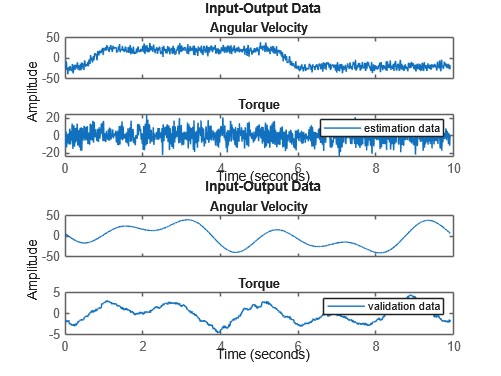

% Prepariamo i dati di validazione
vData = iddata(yv3,uv3,5e-4,InputName="Torque", ...
    OutputName="Angular Velocity",Tstart=0);
% uv3: somma di sinusoidi di frequenza 0.1, 0.3 e 0.5Hz con valore di picco
% pari a 40 rad/s.
vData = idresamp(vData,[1 10]);
vData.Name = "validation data";
% Plottiamo i dati
subplot (2,1,1)
plot(eData)
legend show
subplot (2,1,2)
plot(vData)
legend show

% Specifichiamo i nomi dei regressori in ingresso e uscita
output_name = "Angular Velocity";
input_name = "Torque";
names = [output_name,input_name];
% Cerchiamo poi l'ordine ottimo dei regressori nel range 1:10 e il delay
% nel range 0:2
V=arxstruc(eData,vData,struc((1:10),(1:10),(0:2)));
NN=selstruc(V,'aic')

NN =      3     6     1


% Creiamo l'oggetto dei regressori
lreg=linearRegressor(names,{(1:3),(0:4)});
% I regressori utilizzati dal modello sono
getreg(lreg)

ans = 8×1 string array
    "Angular Velocity(t-1)"
    "Angular Velocity(t-2)"
    "Angular Velocity(t-3)"
    "Torque(t)"
    "Torque(t-1)"
    "Torque(t-2)"
    "Torque(t-3)"
    "Torque(t-4)"


% Possiamo utilizzare una rete con 3 hidden layer di
% dimensioni 4, 6 e 1 usando la funzione feeforward. Le funzioni di
% attivazione sono tanh.
net3=idNeuralNetwork(feedforwardnet([4 6 1]));

rng default % Settiamo il random number generator in questo modo per la riproducibilità

% Scegliamo come opzione di training settando Focus in modalità simulation.
% Quest'opzione ci permette di avere performance migliori del modello in
% modalità closed loop.
opt = nlarxOptions(Focus="simulation");
% Come metodo di ricerca scegliamo lsqnonlin (least square non linear) e numero massimo di iterazioni
% pari a 20
opt.SearchMethod = "lsqnonlin";
opt.SearchOptions.MaxIterations = 20;
nlarx3 = nlarx(eData,lreg,net3,opt)


nlarx3 =

Nonlinear ARX model with 1 output and 1 input
  Inputs: Torque
  Outputs: Angular Velocity

Regressors:
  Linear regressors in variables Angular Velocity, Torque
  List of all regressors

Output function: Shallow network of Deep Learning Toolbox
Sample time: 0.005 seconds

Status:                                                     
Estimated using NLARX on time domain data "estimation data".
Fit to estimation data: 70.32% (simulation focus)           
FPE: 1.108, MSE: 38.21                                      



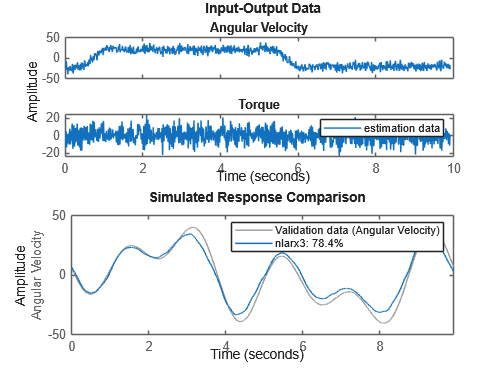

% Compariamo i risultati con i dati di validazione
compare(vData,nlarx3)
legend show

% Proviamo poi una regression neural network con due hidden layer
% con 5 e 3 neuroni e funzione di attivazione relu.
net1 = idNeuralNetwork([5 3],"relu",NetworkType="RegressionNeuralNetwork");

nlarx1 = nlarx(eData,lreg,net1,opt)


nlarx1 =

Nonlinear ARX model with 1 output and 1 input
  Inputs: Torque
  Outputs: Angular Velocity

Regressors:
  Linear regressors in variables Angular Velocity, Torque
  List of all regressors

Output function: Regression neural network
Sample time: 0.005 seconds

Status:                                                     
Estimated using NLARX on time domain data "estimation data".
Fit to estimation data: 71.74% (simulation focus)           
FPE: 1.072, MSE: 34.66                                      



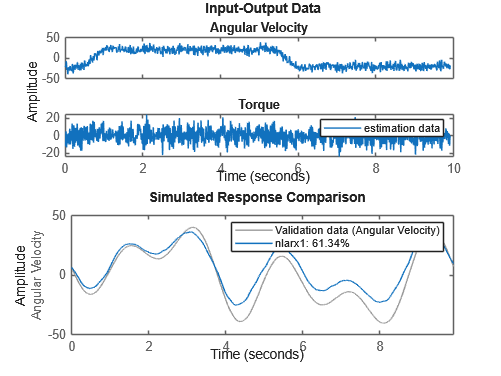

% Verifichiamo come si comporta il modello rispetto ai dati di validazione
compare(vData,nlarx1)
legend show

% Creiamo ora una rete deep learning per provare ad ottenere un fit migliore 
% del modello. La rete è cosi formata: primo hidden layer con 10 neuroni
% e funzione di attivazione tanh, secondo hidden laer con 5 neuroni e
% funzione di attivazione sigmoidale, terzo hidden layer con 2 neuroni e
% funzione di attivazione gelu
net2 = idNeuralNetwork([10 5 2],["tanh","sigmoid","gelu"],NetworkType="dlnetwork");
% Per evitare che il processo di training duri troppo, suddividiamo il
% dataset in 500 sample senza sovrapposizione
eDataSplit = utSegmentData1(eData,500,500);
% Scegliamo come metodo di ricerca Levenberg-Marquardt con numero di
% iterazioni massimo pari a 5
opt.SearchMethod = "lm";
opt.SearchOptions.MaxIterations = 5;
% Come output del modello NARX scegliamo net2
nlarx2 = nlarx(eDataSplit,lreg,net2,opt)


nlarx2 =

Nonlinear ARX model with 1 output and 1 input
  Inputs: Torque
  Outputs: Angular Velocity

Regressors:
  Linear regressors in variables Angular Velocity, Torque
  List of all regressors

Output function: Deep learning network
Sample time: 0.005 seconds

Status:                                                        
Estimated using NLARX on time domain data "estimation data".   
Fit to estimation data: [70.79 18.71 71.25]% (simulation focus)
FPE: 1.119, MSE: [29.83 24.39 28.29]                           



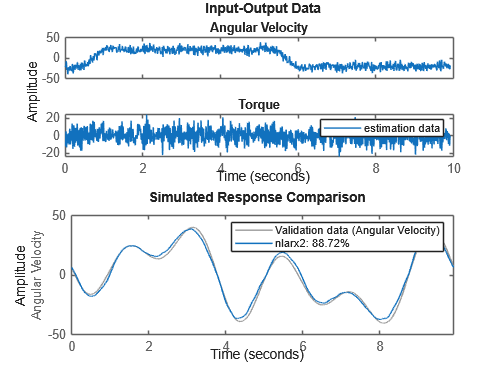

% Compariamo il modello creato con i dati di validazione
compare(vData,nlarx2)

% Possiamo anche identificare i modelli HW utilizzando differenti
% configurazioni delle reti neuronali per mappare i regressori in uscita

% Per prima utilizziamo una regression neural network con due hidden layer
% di dimensione 5 e 7 e funzioni di attivazione sigmoidali
net4 = idNeuralNetwork([5 7],"sigmoid",NetworkType="RegressionNeuralNetwork");
% Stimiamo il modello HW con non linearità solo in uscita e il cui ordine
% utilizziamo quello trovato prima con la funzione selstruc
nb = 6;
nf = 3;
nk = 1;
nlhw1 = nlhw(eData,[nb,nf,nk],[],net4)


nlhw1 =

Hammerstein-Wiener model with 1 output and 1 input

Linear transfer function corresponding to the orders nb = 6, nf = 3, nk = 1

Input nonlinearity: None
Output nonlinearity: Regression neural network
Sample time: 0.005 seconds

Status:                                                    
Estimated using NLHW on time domain data "estimation data".
Fit to estima

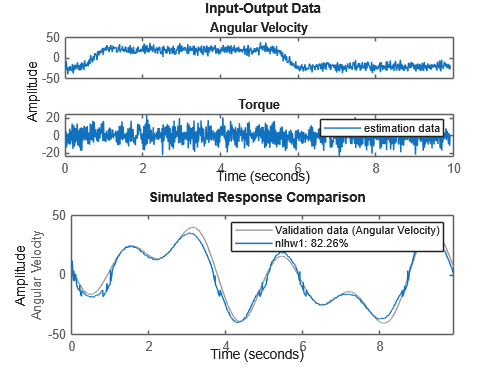

% Compariamo il modello con i dati di validazione
compare(vData,nlhw1)

% Utilizziamo come regressore sempre lo stesso, ma lo poniamo solo in
% ingresso al modello 
nlhw2 = nlhw(eData,[nb,nf,nk],net4,[])


nlhw2 =

Hammerstein-Wiener model with 1 output and 1 input

Linear transfer function corresponding to the orders nb = 6, nf = 3, nk = 1

Input nonlinearity: Regression neural network
Output nonlinearity: None
Sample time: 0.005 seconds

Status:                                                    
Estimated using NLHW on time domain data "estimation data".
Fit to estima

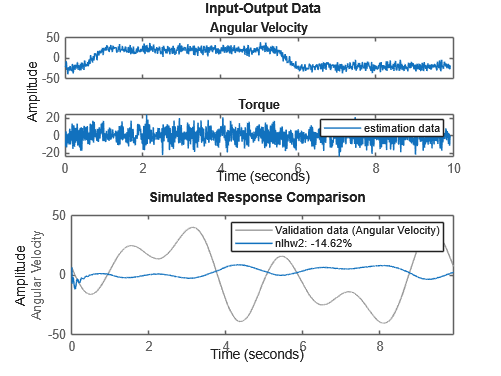

% Compariamo il modello con i dati di validazione
compare(vData,nlhw2)

% Infine utilizziamo il regressore in ingresso e uscita per creare un modello di HW
nlhw3 = nlhw(eData,[nb,nf,nk],net4,net4)


nlhw3 =

Hammerstein-Wiener model with 1 output and 1 input

Linear transfer function corresponding to the orders nb = 6, nf = 3, nk = 1

Input nonlinearity: Regression neural network
Output nonlinearity: Regression neural network
Sample time: 0.005 seconds

Status:                                                    
Estimated using NLHW on time domain data "estimation

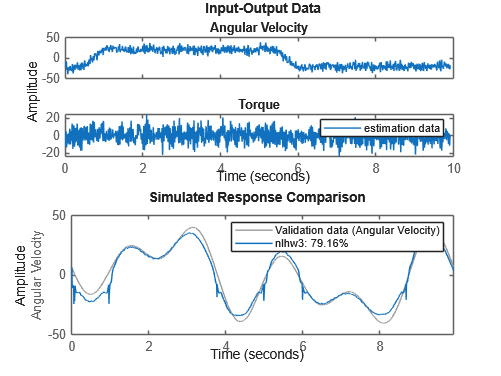

% Compariamo il modello con i dati di validazione
compare(vData,nlhw3)